# Setup Workspace

clc; clear all; close all;

# Satellites Attitude Control - P, PID Control

Proposed plant from Feedback Control of Dynamic Systems (FPE) 8th edition, Pg 738.

$G(s) = \frac{10bs + 10k}{ s^2 + 11 bs + 11k}$ , 

Via physical analysis - Vary as a result of temperature fluctuations but bounded by the range below (all are less/greater than are equal to)


$$0.09 < k < 0.4$$
  


$$0.038\sqrt{\frac{k}{ 10}} < b < 0.2\sqrt{\frac{k}{10}}$$


% Constants - choose the average
k = (0.4 - 0.09)/2;
b = (0.2*sqrt(k/10) - 0.038*sqrt(k/10)/2);

% Plant
Num = [10*b, 10*k];
Den = [1, 11*b, 11*k]; % Reduced 
Den_og = [1, 11*b, 11*k, 0, 0]; % orginal 
G_s = tf(Num, Den);

G_s_orig = tf(Num, Den_og)

G_s_orig =
 
        0.2253 s + 1.55
  ----------------------------
  s^4 + 0.2479 s^3 + 1.705 s^2
 
Continuous-time transfer function.



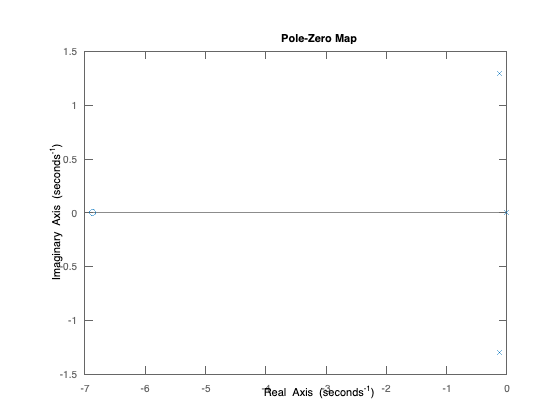

figure;
pzplot(G_s_orig)

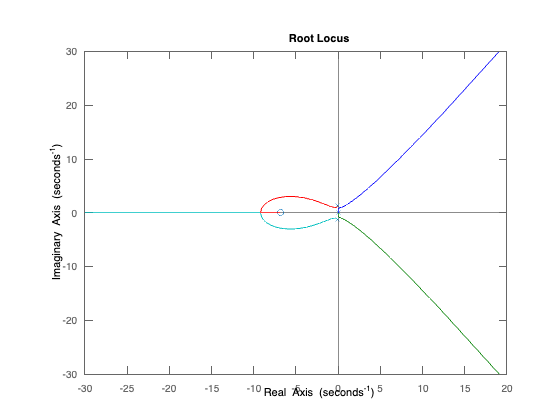


figure;
rlocus(G_s_orig)

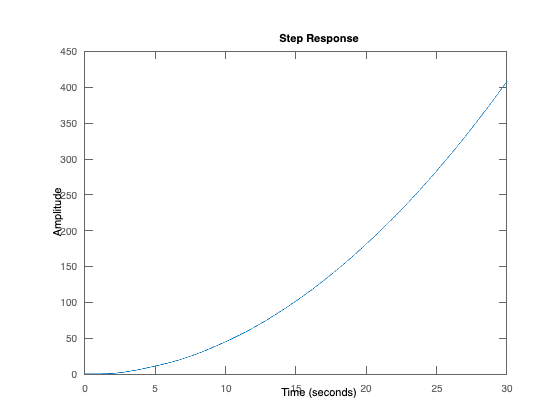


% Step Response 
t = linspace(0, 30, 1000); %60sec

figure;
step(G_s_orig, t)

%Plant_info = stepinfo(G_s);

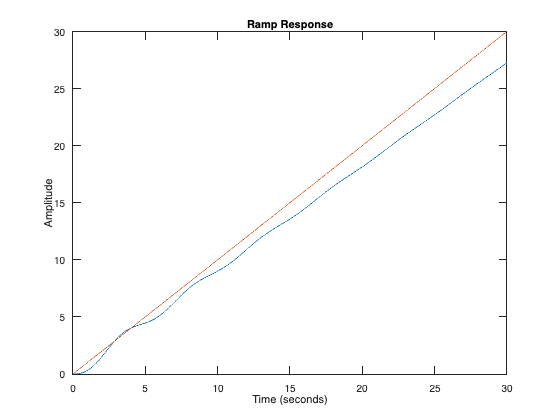

% Ramp response
alpha = 1; % ramp input slope
u_ramp = alpha * t; % ramp input
y_ramp = lsim(G_s, u_ramp, t, [0]); % compute trajectory for linear system for zero initial condition
figure
plot(t, y_ramp, t, u_ramp);
xlabel('Time (seconds)')
ylabel('Amplitude')
title('Ramp Response')

figure
pzplot(G_s_orig); grid off

#  Proportional Controller

s = tf('s');
kP = [1,2.3,10];
%kD = 0.3;

%D_PD = kP + kD*s;
D_P = kP;

% Steps
R = 1;
[y_p, t1] = step(R * feedback(D_P(1) * G_s, 1), 60*60);
[y_p3, t2] = step(R * feedback(D_P(2) * G_s, 1), 60*60);
[y_p10, t3] = step(R * feedback(D_P(3) * G_s, 1), 60*60);

G_s_orig_Cl = feedback(D_P(1) * G_s_orig,1)

G_s_orig_Cl =
 
                          
           0.2253 s + 1.55
                          
  ---------------------------------
                                   
  s^4 + 0.2479 s^3 + 1.705 s^2     
                                   
                  + 0.2253 s + 1.55
                                   
 
Continuous-time transfer function.




% Plot Response 
figure;
subplot(2,1,1)
plot(t1, y_p)
hold on
plot(t2, y_p3)
hold on
plot(t3, y_p10)
xlim([0 5])
title('Response to Step Reference (P)');
legend('kp=1', 'kp=3', 'kp=10')
%CL_P_info = stepinfo(R * feedback(D_P * G_s, 10))

%Overshoot
OS_kp1 = (max(y_p) - 1)*100;
OS_kp3 = (max(y_p3) - 1)*100;
OS_kp10 = (max(y_p10) - 1)*100;

fprintf('Overshoot = %f percent', OS_kp1)

Overshoot = -19.937155 percent

fprintf('Overshoot = %f percent', OS_kp3)

Overshoot = 9.559112 percent

fprintf('Overshoot = %f percent', OS_kp10)

Overshoot = 30.394183 percent

% Error plot
ess_p = R-y_p;
ess_p3 = R-y_p3;
ess_p10 = R-y_p10;

fprintf('Steady state error = %f', ess_p(end))

Steady state error = 0.523810

fprintf('Steady state error = %f', ess_p3(end))

Steady state error = 0.323529

fprintf('Steady state error = %f', ess_p10(end))

Steady state error = 0.099099

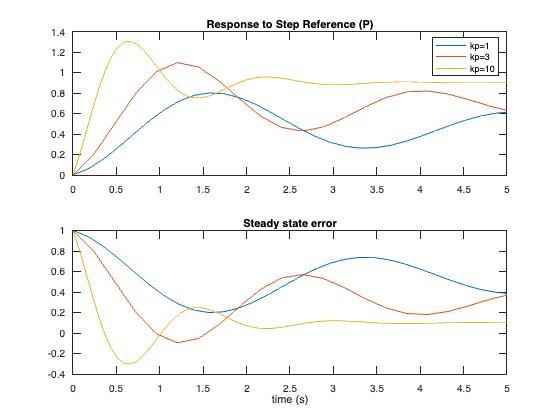

subplot(2,1,2)
plot(t1, ess_p)
hold on
plot(t2, ess_p3)
hold on
plot(t3, ess_p10)
%ylim([-0.5 1])
xlim([0 5])
title('Steady state error');
%legend('kp=1', 'kp=3', 'kp=10')
xlabel('time (s)')

#  Original Plant w/ Proportional Controller

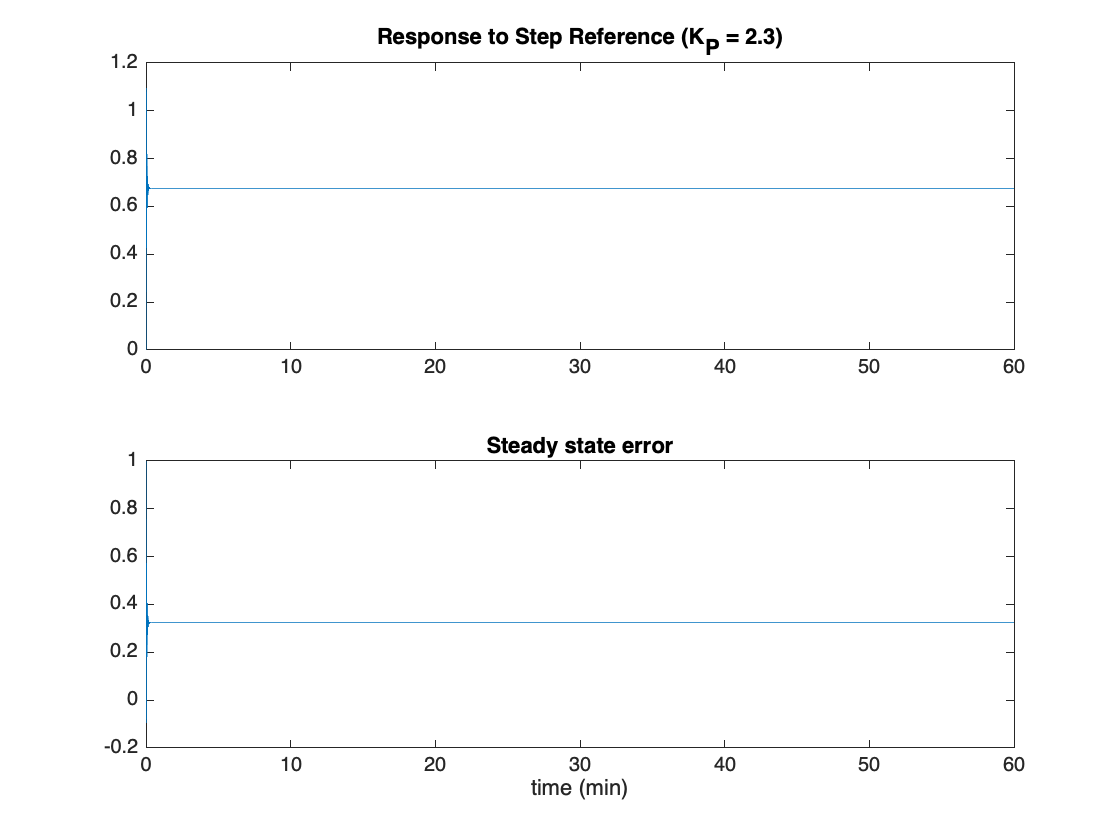

figure;
subplot(2,1,1)
plot(t2/60, y_p3)
title('Response to Step Reference (K_{P} = 2.3)');
subplot(2,1,2)
plot(t2/60, ess_p3)
title('Steady state error');
xlabel('time (min)')

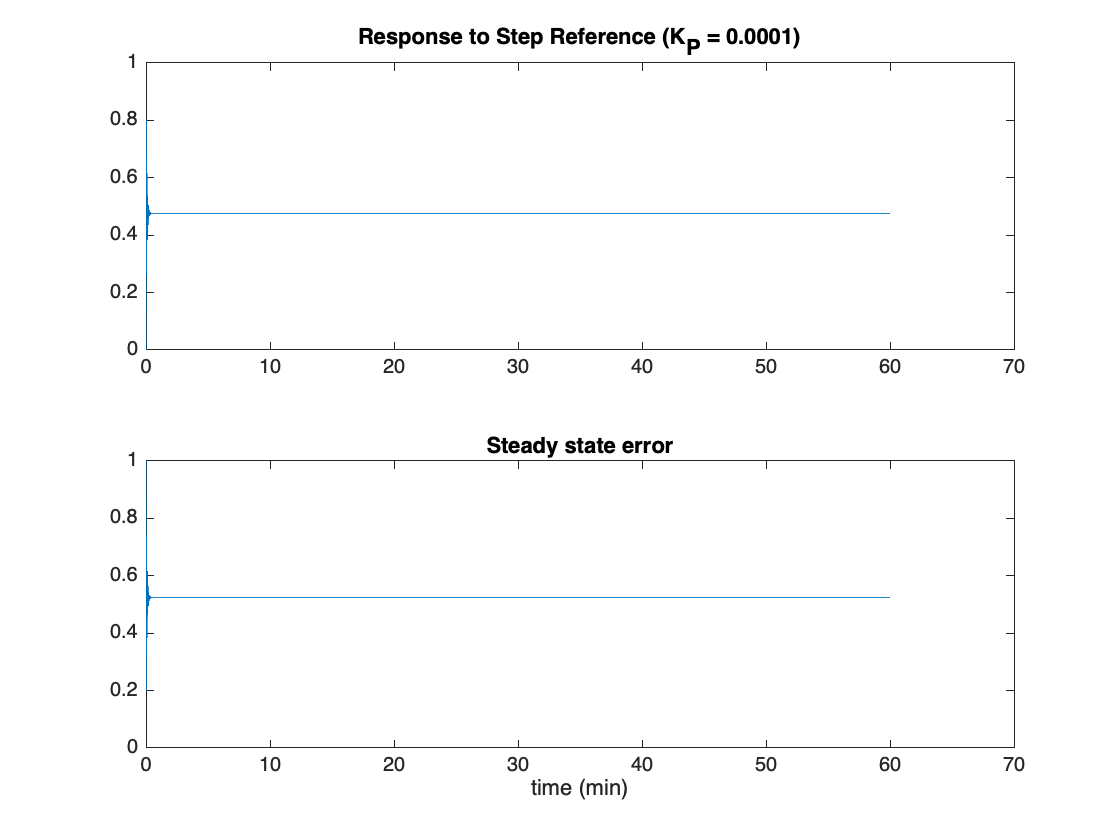

figure;
subplot(2,1,1)
plot(t1/60, y_p)
title('Response to Step Reference (K_{P} = 0.0001)');
subplot(2,1,2)
plot(t1/60, ess_p)
title('Steady state error');
xlabel('time (min)')

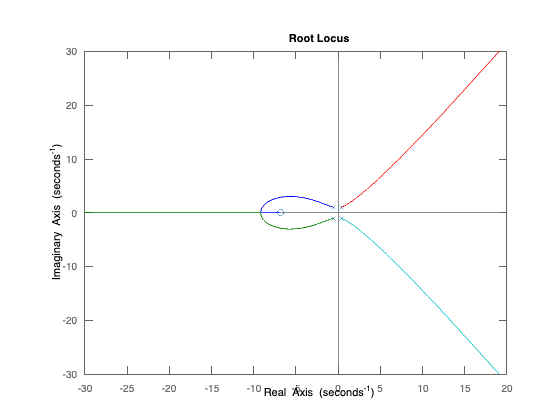


figure;
rlocus(G_s_orig_Cl)

#  Proportional-Integral-Derivative Controller

s = tf('s');
kP = 2.3;
kD = 0.99;
kI = [1, 2, 2.5];

D_PID_1 = kP + kD*s;
D_PID_2 = kP + kI(2)/s + kD*s;
D_PID_3 = kP + kI(3)/s + kD*s;
D_PID_4 = 0.001*kP + .01/s + kD*s;

% Plot Response to Step Reference
R = 1;
[y_pid1, t4] = step(R * feedback(D_PID_1 * G_s, 1), 30);
[y_pid2, t5] = step(R * feedback(D_PID_2 * G_s, 1), 30);
[y_pid3, t6] = step(R * feedback(D_PID_3 * G_s, 1), 30);
infooo = stepinfo(R * feedback(D_PID_3 * G_s, 1), 30);

G_Cl1 = feedback(D_PID_1 * G_s, 1)

G_Cl1 =
 
  0.2231 s^2 + 2.053 s + 3.565
  ----------------------------
   1.223 s^2 + 2.301 s + 5.27
 
Continuous-time transfer function.



G_Cl2 = feedback(D_PID_2 * G_s, 1)

G_Cl2 =
 
                                   
  0.2231 s^3 + 2.053 s^2           
                                   
                    + 4.016 s + 3.1
                                   
  ---------------------------------
                                   
  1.223 s^3 + 2.301 s^2 + 5.721 s  
                                   
                              + 3.1
                                   
 
Continuous-time transfer function.



G_Cl3 = feedback(D_PID_3 * G_s, 1)

G_Cl3 =
 
                                   
  0.2231 s^3 + 2.053 s^2           
                                   
                  + 4.128 s + 3.875
                                   
  ---------------------------------
                                   
  1.223 s^3 + 2.301 s^2 + 5.833 s  
                                   
                            + 3.875
                                   
 
Continuous-time transfer function.



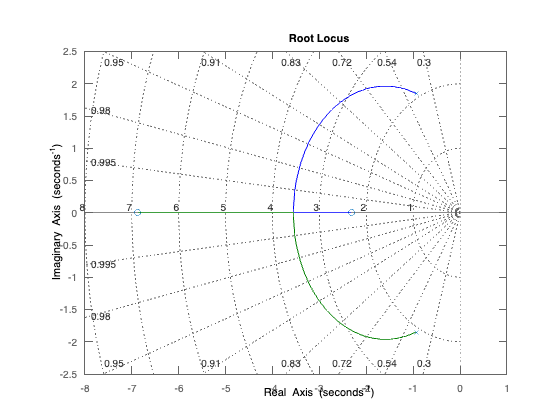


figure
rlocus(G_Cl1); grid on

%xlim([-1 0.5])
%ylim([-0.5 1])

% Overshoot
OS_pid1 = (max(y_pid1) - 1)*100

OS_pid1 = -9.4225

OS_pid2 = (max(y_pid2) - 1)*100

OS_pid2 = 5.8806

OS_pid3 = (max(y_pid3) - 1)*100

OS_pid3 = 9.4849

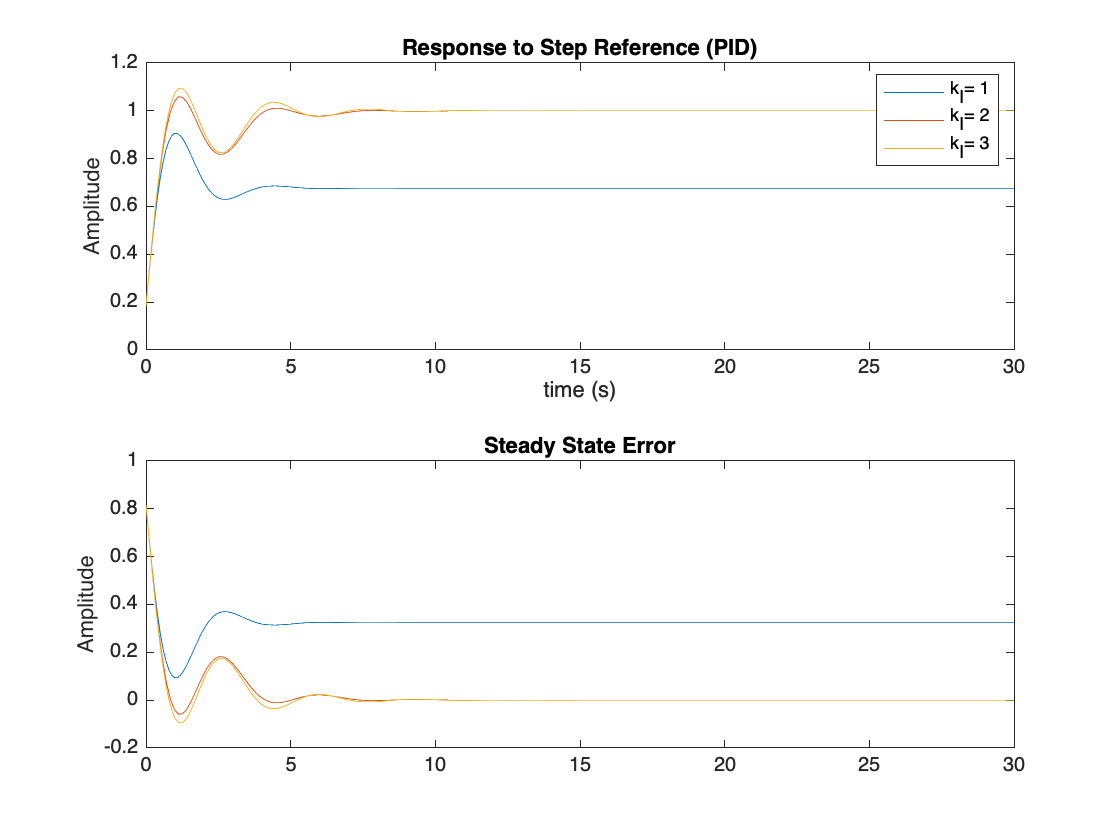


% errors
ess_Step_pid = R-y_pid1;
ess_Step_pid2 = R-y_pid2;
ess_Step_pid3 = R-y_pid3;

figure;
subplot(2,1,1)
plot(t4, y_pid1)
hold on
plot(t5, y_pid2)
hold on
plot(t6, y_pid3)
title('Response to Step Reference (PID)');
xlabel('time (s)')
ylabel('Amplitude')
legend('k_{I}= 1', 'k_{I}= 2', 'k_{I}= 3')
subplot(2,1,2)
plot(t4, ess_Step_pid)
hold on
plot(t5, ess_Step_pid2)
hold on
plot(t6, ess_Step_pid3)

title('Steady State Error');
ylabel('Amplitude')

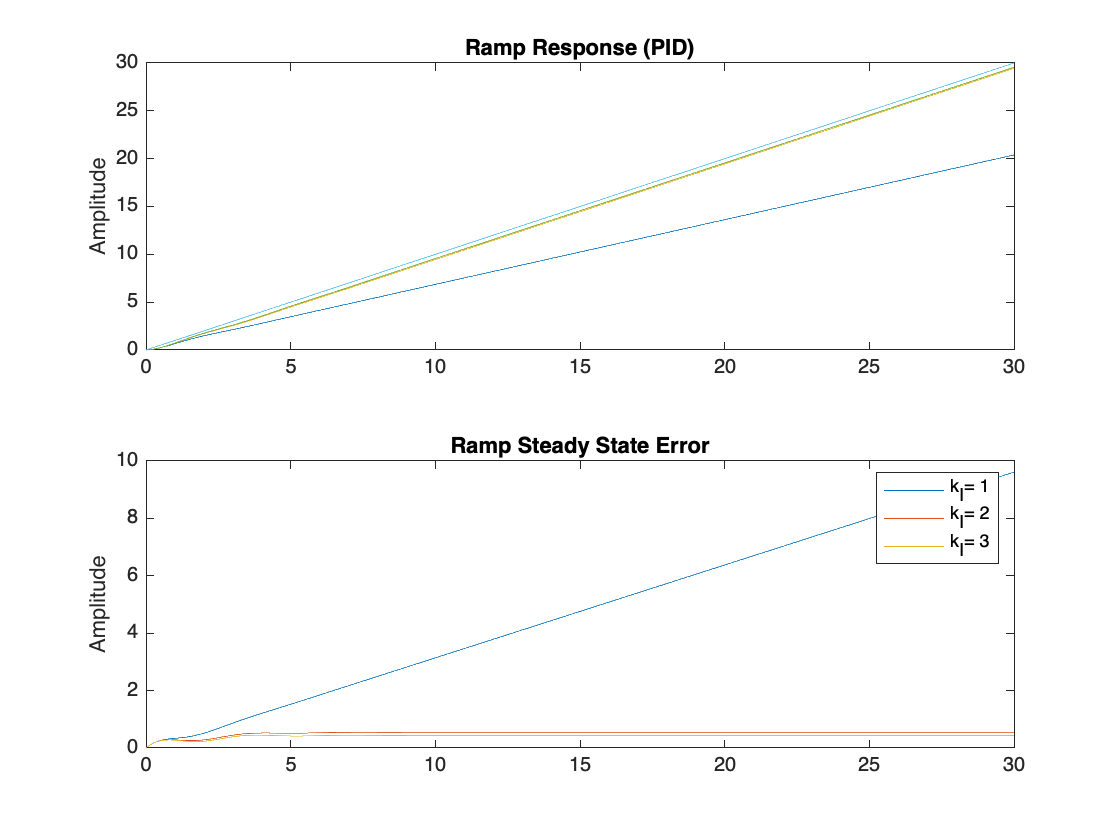


% Ramp response
alpha = 1; % ramp input slope
u_ramp = alpha * t; % ramp input
y_rampPID = lsim(G_Cl1, u_ramp, t, [0]); % compute trajectory for linear system for zero initial condition
y_rampPID2 = lsim(G_Cl2, u_ramp, t, [0]); % compute trajectory for linear system for zero initial condition
y_rampPID3 = lsim(G_Cl3, u_ramp, t, [0]); % compute trajectory for linear system for zero initial condition

figure;
subplot(2,1,1)
plot(t, y_rampPID, t, u_ramp);
hold on
plot(t, y_rampPID2, t, u_ramp);
hold on
plot(t, y_rampPID3, t, u_ramp);
ylabel('Amplitude')
title('Ramp Response (PID)')

% Error 
ess_Ramp_PID = u_ramp - y_rampPID';
ess_Ramp_PID2 = u_ramp - y_rampPID2';
ess_Ramp_PID3 = u_ramp - y_rampPID3';

subplot(2,1,2)
plot(t, ess_Ramp_PID);
hold on
plot(t, ess_Ramp_PID2);
hold on
plot(t, ess_Ramp_PID3);
ylabel('Amplitude')
title('Ramp Steady State Error')
legend('k_{I}= 1', 'k_{I}= 2', 'k_{I}= 3')


% Ramp Errors
RampError = ess_Ramp_PID(end)

RampError = 9.6117

RampError2 = ess_Ramp_PID2(end)

RampError2 = 0.5500

RampError3= ess_Ramp_PID3(end)

RampError3 = 0.4400

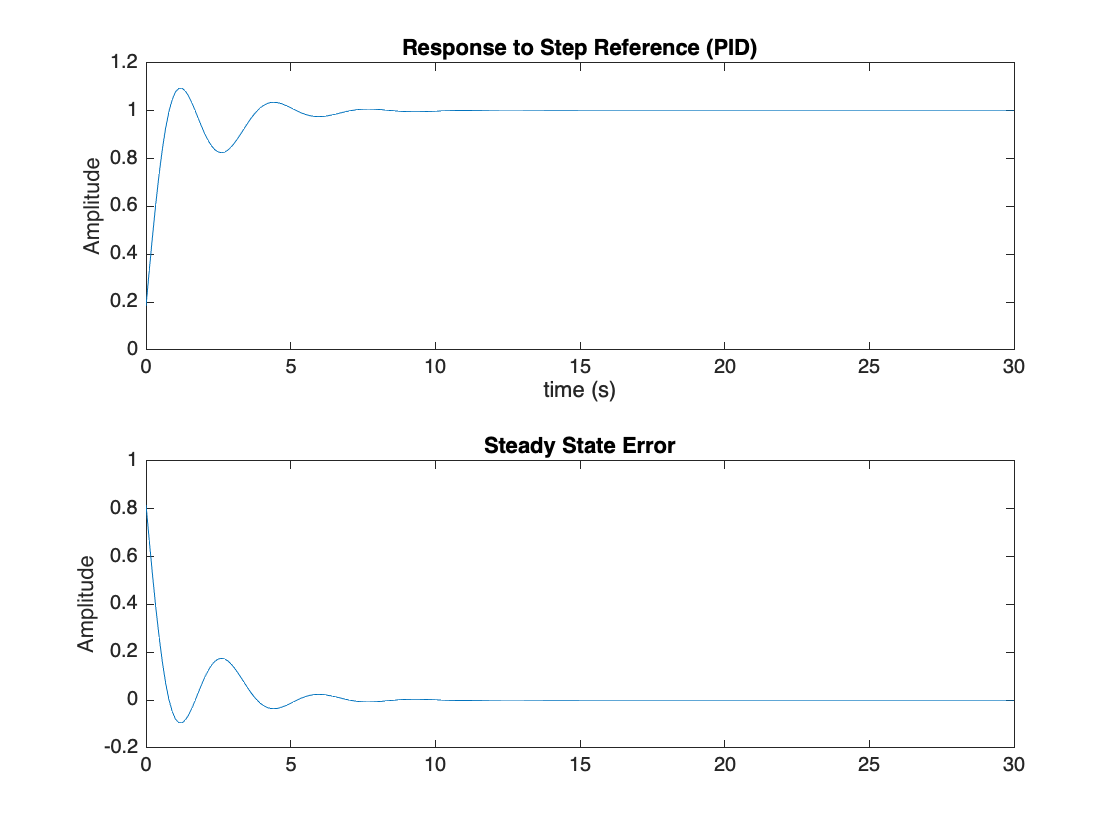


% Final PID plots
figure;
subplot(2,1,1)
plot(t6, y_pid3)
title('Response to Step Reference (PID)');
xlabel('time (s)')
ylabel('Amplitude')

subplot(2,1,2)
plot(t6, ess_Step_pid3)
title('Steady State Error');
ylabel('Amplitude')

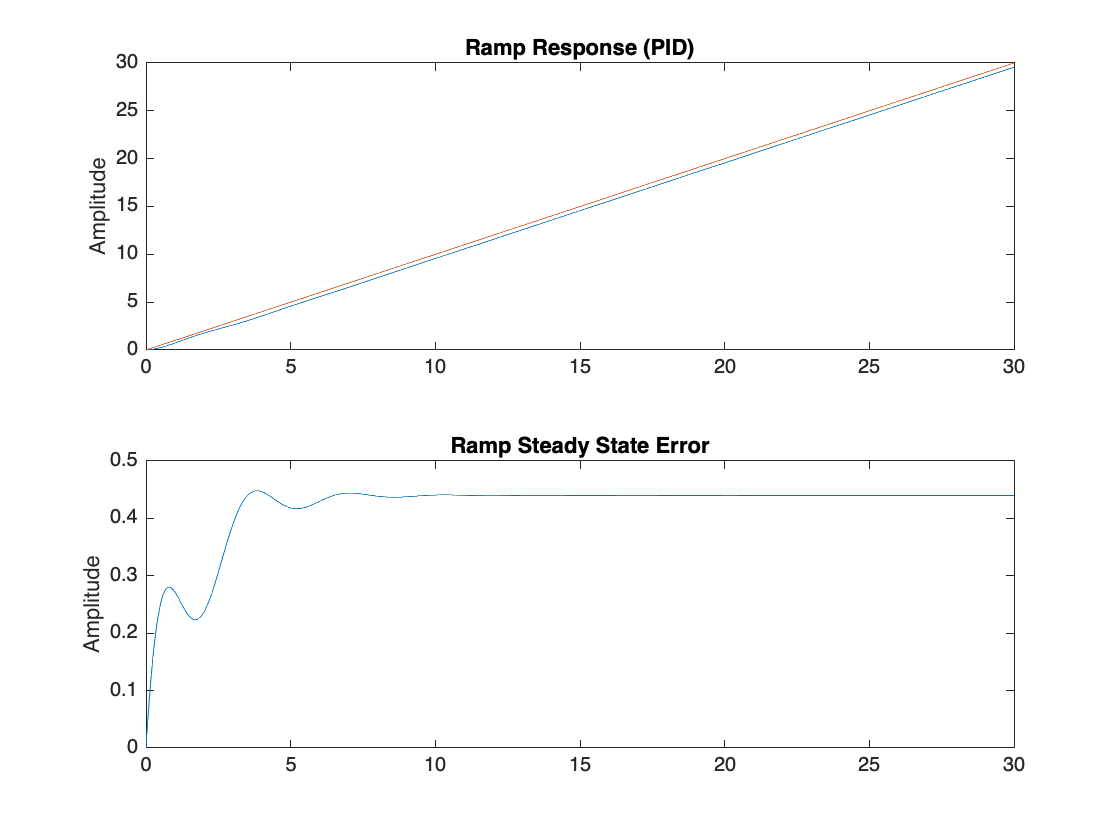


% Ramps
figure;
subplot(2,1,1)
plot(t, y_rampPID3, t, u_ramp);
ylabel('Amplitude')
title('Ramp Response (PID)')

subplot(2,1,2)
plot(t, ess_Ramp_PID3);
ylabel('Amplitude')
title('Ramp Steady State Error')

# Original Plant with PID

kP = 2.3; kI = 2.5; kD = 0.99

kD = 0.9900

%D_PID_4 = 0.0001 + .00001/s + 0.99*s;
D_PID_4 = kP + kI/s + kD*s;

[y_pid4, t7] = step(R * feedback(D_PID_4 * G_s_orig_Cl, 1), 60*60*24*5);
stepinfo(R * feedback(D_PID_4 * G_s_orig_Cl, 1), 60*60*24*5);

Gs_CL_PID_orig = feedback(D_PID_4 * G_s_orig_Cl, 1)

Gs_CL_PID_orig =
 
                                   
  0.2231 s^3 + 2.053 s^2           
                                   
                  + 4.128 s + 3.875
                                   
  ---------------------------------
                                   
  s^5 + 0.2479 s^4 + 1.928 s^3     
                                   
          + 2.278 s^2 + 5.678 s    
                                   
                            + 3.875
                                   
 
Continuous-time transfer function.



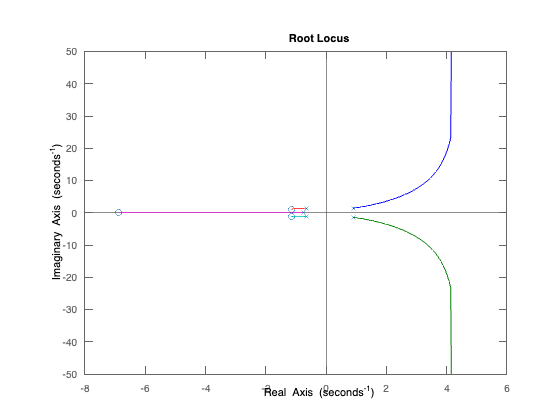


figure;
rlocus(Gs_CL_PID_orig)


ess_Step_pid4 = R-y_pid4;
ess_Step_pid4(end)

ans = NaN

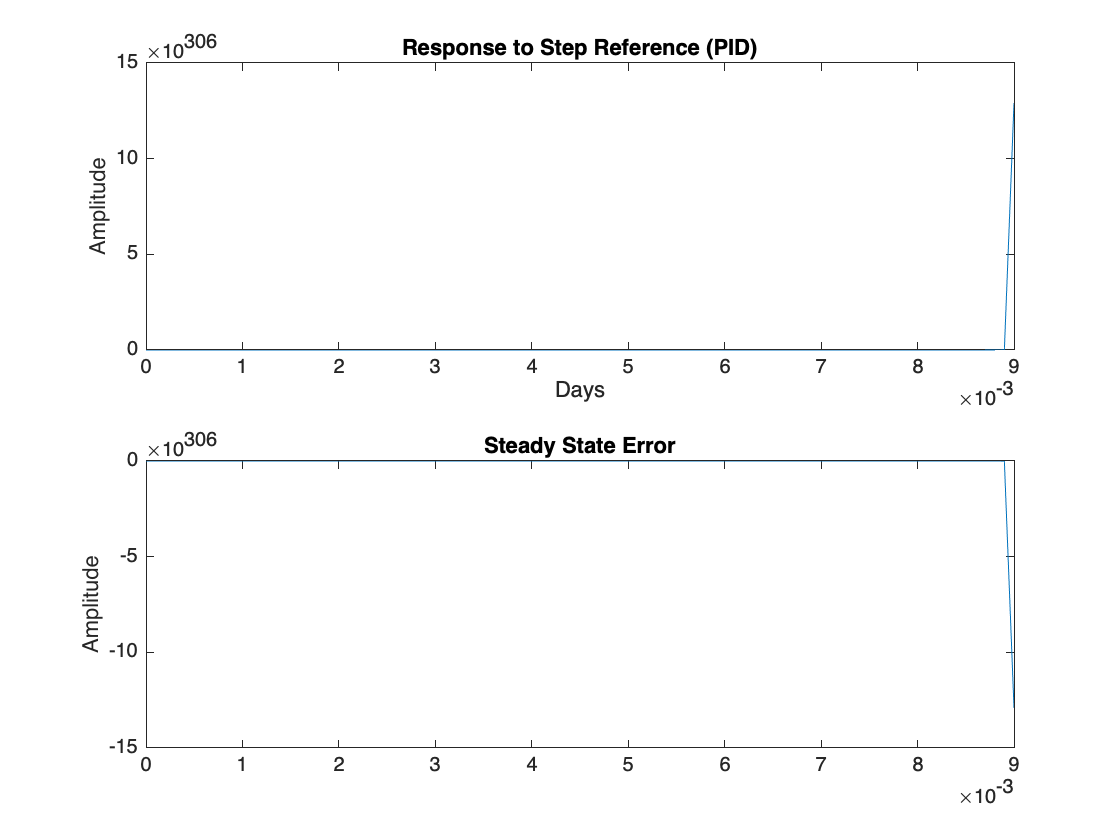


figure;
subplot(2,1,1)
plot(t7/(60*60*24), y_pid4)
title('Response to Step Reference (PID)');
xlabel('Days')
ylabel('Amplitude')

subplot(2,1,2)
plot(t7/(60*60*24), ess_Step_pid4)
title('Steady State Error');
ylabel('Amplitude')

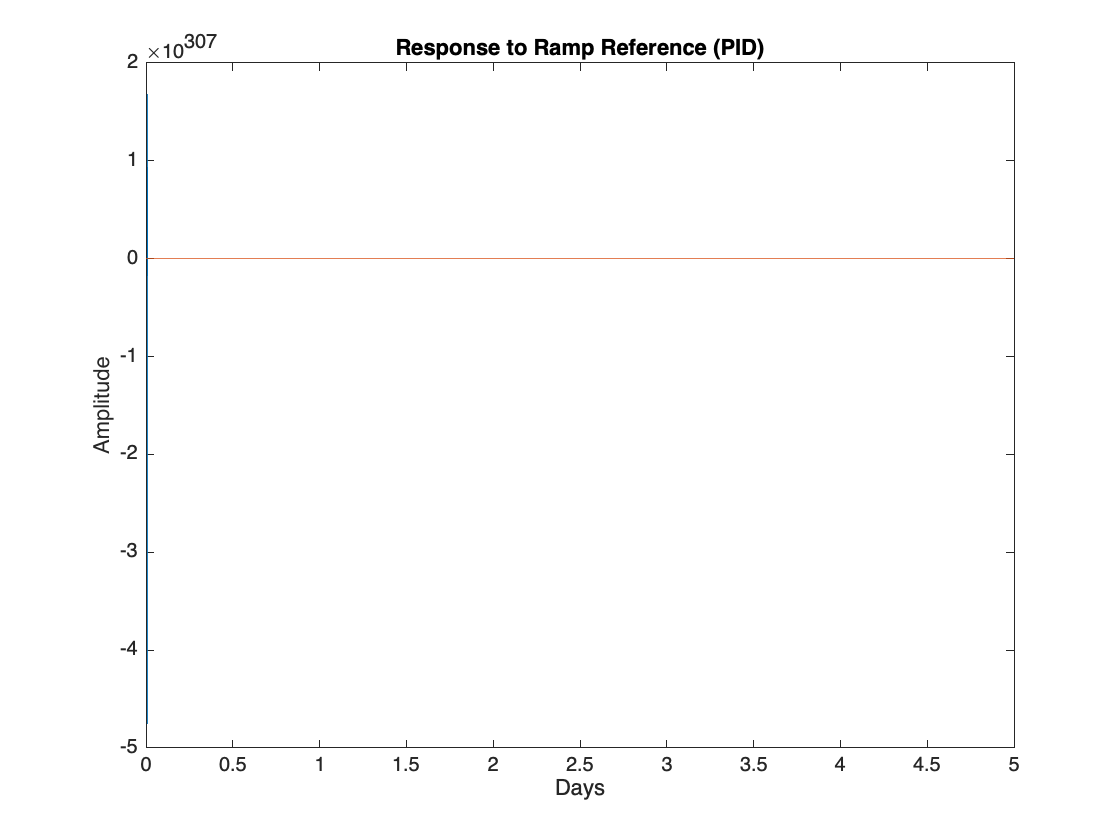


tt = linspace(0,60*60*24*5, 60*60*24*5);
u_ramp = alpha * tt; % ramp input

y_rampPID_orig = lsim(Gs_CL_PID_orig, u_ramp, tt, [0]); % compute trajectory for linear system for zero initial condition

figure;
plot(tt/(60*60*24), y_rampPID_orig, tt/(60*60*24), u_ramp);
title('Response to Ramp Reference (PID)');
xlabel('Days')
ylabel('Amplitude')


ess_PID_orig = u_ramp(end) - y_rampPID_orig(end)

ess_PID_orig = NaN

exxxxx = (s+3+3i)*(s+3-3i)

exxxxx =
 
  s^2 + 6 s + 18
 
Continuous-time transfer function.

